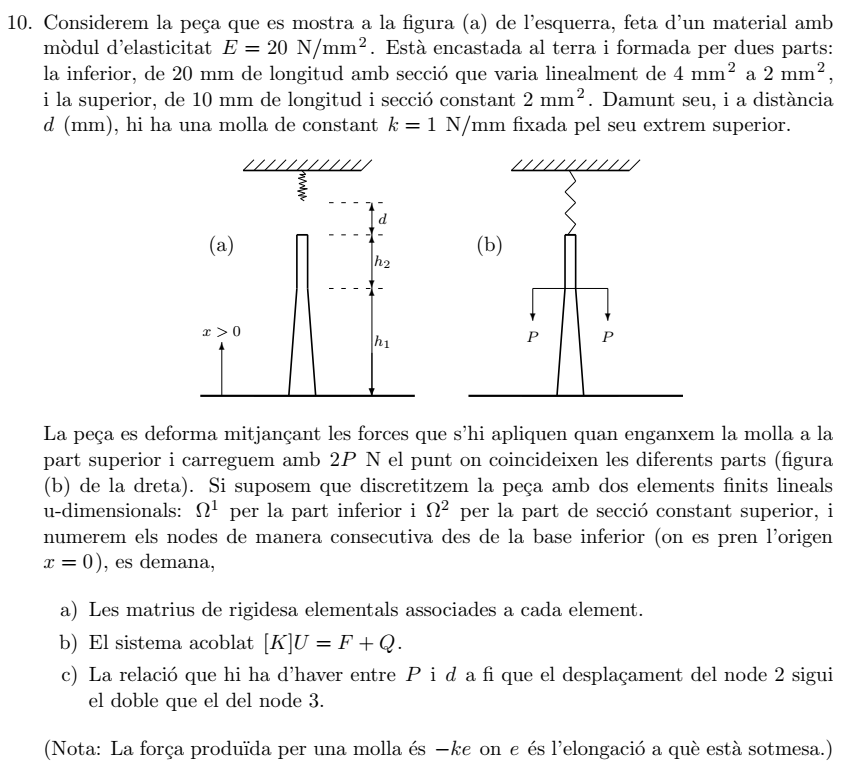

#### Equació de l'elesticitat v.s l'equació model

L'equació del model físic del problema és l'equació de l'elasticitat,


$$-\frac{\mathrm{d}}{\mathrm{d}x}\left(E(x)A(x)\frac{\mathrm{d}u}
{\mathrm{d} x}\right) = f(x),$$


amb el mòdul de Young constant al llarg de tota la peça, $E = 20$  N/mm$ $\text{N/mm}^2$, i $f\equiv 0$, ja que no tenim en compte el pes de la peça (no se'ns dóna ni la densitat ni el pes específic). Aquesta equació es correspon amb l'equació model amb què hem desenvolupat la teoria per al cas 1D,


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(a_{1}(x)\frac{\mathrm{d}u}{\mathrm{d}x}\right)+a_{0}(x)u = f(x),$$


si identifiquem,


$$a_{1}(x) = EA(x) = \begin{cases} E\left(4 - \frac{x}{10}\right), & 0\le x \le 20,\\ 
2E, & 20 \le x \le 30.
\end{cases}$$


i


$$a_{0}(x) =0, \quad 0\le x\le 30.$$


clearvars
close all
%Coefficients 
E = 20; %N/mm^2;
k = 1; %N/mm

syms x P d 
syms U [3 1]
syms Q [3 1]
%syms K1 K2 [2 2]

K = sym(zeros(3));

K1 = sym('K__1');
K2 = sym('K__2');

#### Element 1

Per a aquest element $A(x) = 4-\frac{x}{10}$, i les funcions de forma i les seves derivades són:


$$\begin{array}{ll}
\Psi_{1}^{1} (x) = 1-\frac{x}{20}, & \frac{\mathrm{d}\Psi_{1}^{1}}{\mathrm{d} x} (x) = -\frac{1}{20},\\
\Psi_{2}^{1}(x) = \frac{x}{20}, & \frac{\mathrm{d}\Psi_{2}^{1}}{\mathrm{d} x}(x) = \frac{1}{20},
\end{array}$$


$x\in\Omega^{1} = [0,20]$. Calculem  la seva matriu de rigidesa, $K^{1} = K^{1,1} + K^{1,0}$. Recordem que les components de $K^{1,1}$ i $K^{1,0}$ vénen donades per les integrals:


$$\begin{array}{l}
K^{1,1}_{ij} = \int_{0}^{20} a_{1}(x) \frac{\mathrm{d}\Psi^{1}_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\Psi^{1}_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x = E\int_{0}^{20} A(x) \frac{\mathrm{d}\Psi^{1}_{i}}{\mathrm{d} x}(x)
\frac{\mathrm{d}\Psi^{1}_{j}}{\mathrm{d} x}(x)\mathrm{d} x,\quad i,j = 1,2,\\
K^{1,0}_{ij} = \int_{0}^{20} a_{0}(x) \Psi^{1}_{i}(x)\Psi^{1}_{j}(x)\,\mathrm{d} x = 0,\quad \text{ per a tot $i,j = 1,2$}
\end{array}$$


ja que $a_{0}\equiv 0$ sobre l'element

%Element 1
A1(x) = -x/10+4;
Psi1(x) = [(20-x)/20,x/20];
dPsi1(x) = diff(Psi1(x),x);

K1 = int(A1(x)*E*dPsi1(x)'*dPsi1(x),x,0,20)

$$K1 = \left(\begin{array}{cc} 3 & -3\\ -3 & 3 \end{array}\right)$$

#### Element 2

Aquí la secció és constant, $A\equiv 2$mm, i les funcions de forma i les seves derivades ara són:


$$\begin{array}{ll}
\Psi^{2}_{1} (x) = 3 - \frac{x}{10}, & \frac{\mathrm{d}\Psi^{2}_{1}}{\mathrm{d} x}(x) = -\frac{1}{10},\\
\Psi^{2}_{2}(x) = \frac{x}{10} -2, & \frac{\mathrm{d}\Psi^{2}_{2}}{\mathrm{d} x}(x) = \frac{1}{10},
\end{array}$$


$x\in\Omega^{2} = [20,30]$. Calculem la matriu matriu de rigidesa de l'element, $K^{2} = K^{2,1} + K^{2,0}$. Les components de $K^{2,1}$ i $K^{2,0}$ vénen donades per les integrals:


$$\begin{array}{l}
K^{2,1}_{ij} = \int_{20}^{30} a_{1}(x) \frac{\mathrm{d}\Psi^{2}_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\Psi^{2}_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x = 2E\int_{20}^{30} \frac{\mathrm{d}\Psi^{2}_{i}}{\mathrm{d} x}(x)
\frac{\mathrm{d}\Psi^{2}_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x,\quad i,j = 1,2\\
K^{2,0}_{ij} = \int_{20}^{30} a_{0}(x) \Psi^{2}_{i}(x)\Psi^{2}_{j}(x)\,\mathrm{d} x = 0,\quad \text{per a tot $i,j = 1,2$}
\end{array}$$


com abans, ja que també $a_{0}\equiv 0$ sobre l'element.

%Element 2
A2 = 2;
Psi2(x) = [(30-x)/10, (x-20)/10];
dPsi2(x) = diff(Psi2(x),x);

K2 = int(A2*E*dPsi2(x)'*dPsi2(x),x,20,30)

$$K2 = \left(\begin{array}{cc} 4 & -4\\ -4 & 4 \end{array}\right)$$

#### Sistema acoplat

Acoplem $K^1$ i $K^{2}$ per obtenir la matriu de rigidesa global $K$

% Sistema acoplat
%K = zeros(3);
K(1:2,1:2) =K1;
K(2:3,2:3) = K(2:3,2:3)+K2

$$K = \left(\begin{array}{ccc} 3 & -3 & 0\\ -3 & 7 & -4\\ 0 & -4 & 4 \end{array}\right)$$

y el sistema acoplat $K U = F + Q$, s'escriu: 

assembledSystem = K*U == Q

$$assembledSystem = \left(\begin{array}{c} 3\,U_{1}-3\,U_{2}=Q_{1}\\ 7\,U_{2}-3\,U_{1}-4\,U_{3}=Q_{2}\\ 4\,U_{3}-4\,U_{2}=Q_{3} \end{array}\right)$$

**Remarca: **Notem que $F=0$, ja que $f(x) = 0$, $0 \le x \le 30$, i


$$\begin{array}{l}
F^{1}_{i} = \int_{0}^{20} f(x) \Psi^{1}_{i}(x) \,\mathrm{d} x = 0,\quad\text{ per a } i=1,2,\\
F^{2}_{i} = \int_{20}^{30} f(x)\Psi^{2}_{i}(x)\,\mathrm{d} x = 0,\quad\text{ per a }
i=1,2
\end{array}$$


i, per tant, $F_{1} = F^{1}_{1} = 0$, $F_{2} = F^{1}_{2} + F^{2}_{1} = 0$, $F_{3} = F^{2}_{2} = 0$.

#### Condicions de contorn

- Essencials: $U_{1} = 0$ (la peça està encastada al terra).

- Naturals: $Q_{2} = -2P$ i aquí $Q_{3}$ és la força de recuperació que fa la molla sobre la part superior de la peça. Notem que quan $U_{3} < d$, la molla s'estira exercint una força cap amunt i llavors $Q_{3} > 0$. Per contra, si $U_{3} > d$, la molla es comprimirà i la força de recuperació estarà dirigida cap avall, és a dir $Q_{3} < 0$. Per tant: $Q_{3} = k(d-U_{3})$.

%B.C.:
U(1) = 0, Q = [Q(1);-2*P;k*(d-U(3))]

$$U = \left(\begin{array}{c} 0\\ U_{2}\\ U_{3} \end{array}\right)$$

$$Q = \left(\begin{array}{c} Q_{1}\\ -2\,P\\ d-U_{3} \end{array}\right)$$

Si incorporem les condicions de contorn al sistema acoplat obtenim,

eqns1 = K * U == Q

$$eqns1 = \left(\begin{array}{c} -3\,U_{2}=Q_{1}\\ 7\,U_{2}-4\,U_{3}=-2\,P\\ 4\,U_{3}-4\,U_{2}=d-U_{3} \end{array}\right)$$

#### Sistema reduït

De la primera equació no coneixem $Q_{1}$, així que resolem les altres dues, que formen el *sistema reduït. *Un cop resolt aquest sistema, tenim $U_{2}$ i $U_{3}$i llavors, com primera part del *post-procès* podem substituir a la primera equació per a obtenir $Q_{1}$.

eqns2 = eqns1(2:3)

$$eqns2 = \left(\begin{array}{c} 7\,U_{2}-4\,U_{3}=-2\,P\\ 4\,U_{3}-4\,U_{2}=d-U_{3} \end{array}\right)$$

Solució del sistema reduït,

sols=solve(eqns2, [U(2), U(3)]); 
sols_sistema_reduit = [U2 == sols.U2; U3 == sols.U3]

$$sols\_sistema\_reduit = \left(\begin{array}{c} U_{2}=\frac{4\,d}{19}-\frac{10\,P}{19}\\ U_{3}=\frac{7\,d}{19}-\frac{8\,P}{19} \end{array}\right)$$

Si, d'acord amb l'enunciat, imposem $U_{2} = 2U_{3}$a l'equació de dalt (el desplaçament del node 2 és el doble que el deplaçament del node 3), s'obté:

eqns3=sols.U2 == 2*sols.U3

$$eqns3 = \frac{4\,d}{19}-\frac{10\,P}{19}=\frac{14\,d}{19}-\frac{16\,P}{19}$$

d'on es segueix que la relació buscada entre la distància $d$ i la càrrega $P$ és:

solucio = d == solve(eqns3,d)

$$solucio = d=\frac{3\,P}{5}$$